# Paso 1: Generate Multiple Pitch Candidates

## Inicialización

clc;
clear;
close all;

% Configuración de rutas
audioFolder = 'audios'; % Carpeta con los archivos de audio
resultsFolder = 'results'; % Carpeta para guardar resultados

% Cargar los archivos de audio
audioFiles = dir(fullfile(audioFolder, '*.wav'));
if isempty(audioFiles)
    error('No se encontraron archivos .wav en la carpeta %s.', audioFolder);
end

% Rango de pitch y longitud de salto
RANGE = [50, 400];
HOPLENGTH = 0.01; % En segundos

## Cargar y preprocesar audio

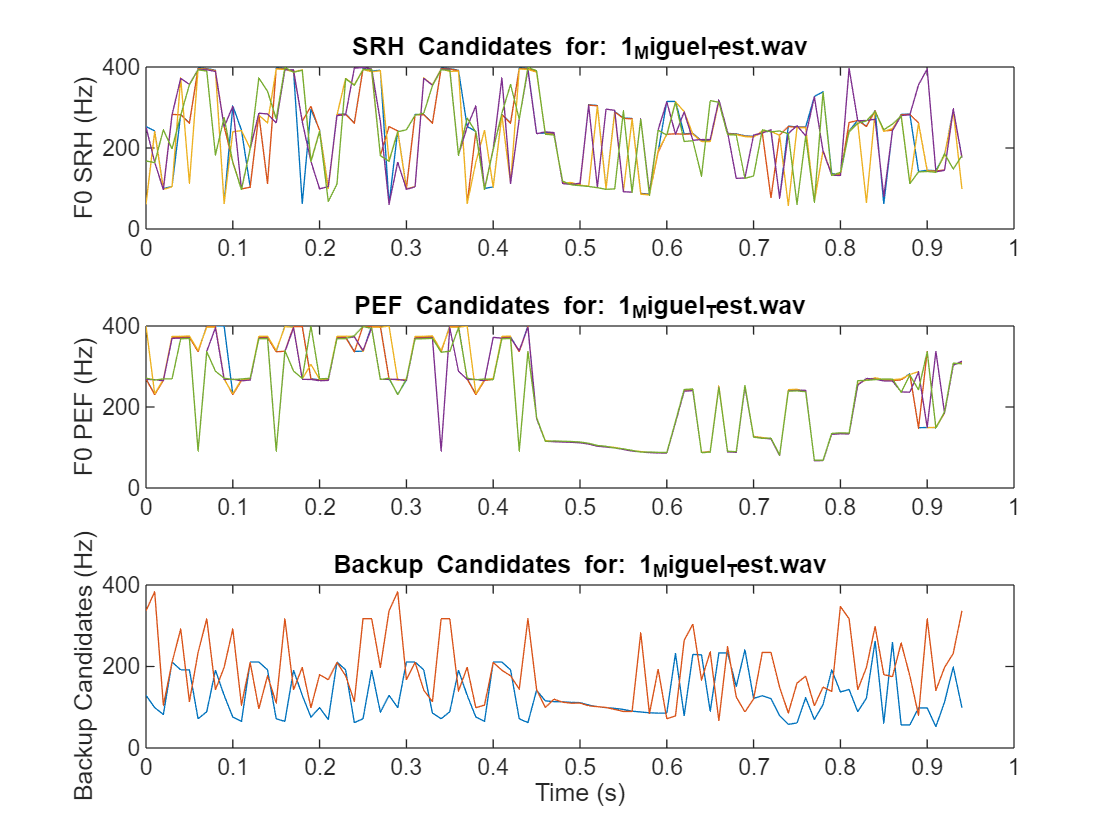

Resultados generados para: 1_Miguel_Test.wav


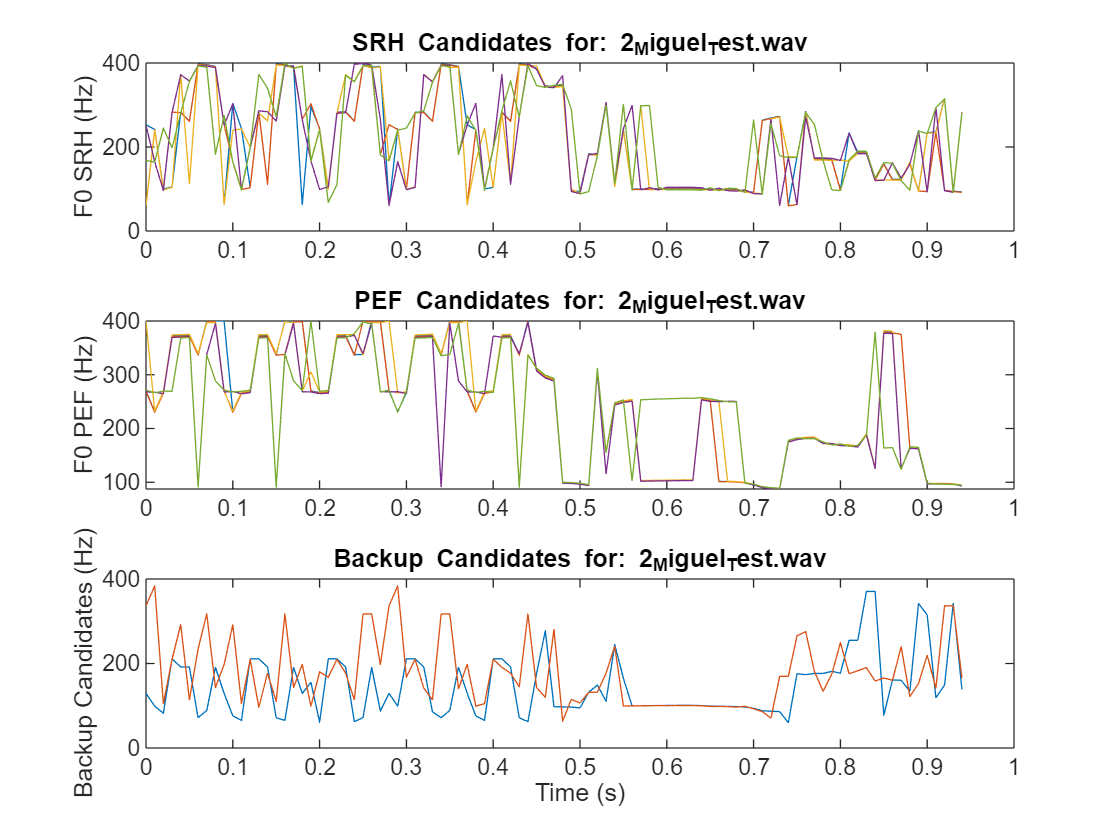

Resultados generados para: 2_Miguel_Test.wav


for fileIndex = 1:length(audioFiles)
    % Leer el archivo de audio
    audioPath = fullfile(audioFolder, audioFiles(fileIndex).name);
    [x, fs] = audioread(audioPath);
    x = x / max(abs(x)); % Normalizar la señal
    t_audio = (0:(length(x)-1)) / fs; % Eje temporal del audio

    % Verificación inicial
    if isempty(x)
        warning(['El archivo ', audioFiles(fileIndex).name, ' está vacío o no se pudo leer correctamente.']);
        continue;
    end

    %%% Generar candidatos con SRH
    try
        % Buffer para SRH
        xBuff_SRH = buffer(x, round(0.025 * fs), round(0.02 * fs), "nodelay");

        % Parámetros del método SRH
        params_SRH = struct(Method="SRH", ...
                            Range=RANGE, ...
                            WindowLength=round(fs * 0.06), ...
                            OverlapLength=round(fs * 0.06 - HOPLENGTH * fs), ...
                            SampleRate=fs, ...
                            NumChannels=size(x, 2), ...
                            SamplesPerChannel=size(x, 1));
        multiCandidate_params_SRH = struct(NumCandidates=5, MinPeakDistance=1);

        % Estimación de pitch y confianza
        [f0_SRH, conf_SRH] = audio.internal.pitch.SRH(xBuff_SRH, x, fs, ...
                                                      params_SRH, ...
                                                      multiCandidate_params_SRH);
    catch ME
        warning(['Error en SRH para el archivo ', audioFiles(fileIndex).name, ': ', ME.message]);
        continue;
    end

    %%% Generar candidatos con PEF
    try
        % Buffer para PEF
        xBuff_PEF = buffer(x, round(0.06 * fs), round(0.05 * fs), "nodelay");

        % Parámetros del método PEF
        params_PEF = struct(Method="PEF", ...
                            Range=RANGE, ...
                            WindowLength=round(fs * 0.06), ...
                            OverlapLength=round(fs * 0.06 - HOPLENGTH * fs), ...
                            SampleRate=fs, ...
                            NumChannels=size(x, 2), ...
                            SamplesPerChannel=size(x, 1));
        multiCandidate_params_PEF = struct(NumCandidates=5, MinPeakDistance=5);

        % Estimación de pitch y confianza
        [f0_PEF, conf_PEF] = audio.internal.pitch.PEF(xBuff_PEF, fs, ...
                                                      params_PEF, ...
                                                      multiCandidate_params_PEF);
    catch ME
        warning(['Error en PEF para el archivo ', audioFiles(fileIndex).name, ': ', ME.message]);
        continue;
    end

    %%% Generar candidatos de respaldo: NCF y CEP
    try
        % Buffer para NCF
        xBuff_NCF = buffer(x, round(0.04 * fs), round(0.03 * fs), "nodelay");
        xBuff_NCF = xBuff_NCF(:, 2:end-1);

        % Parámetros del método NCF
        params_NCF = struct(Method="NCF", ...
                            Range=RANGE, ...
                            WindowLength=round(fs * 0.04), ...
                            OverlapLength=round(fs * 0.04 - HOPLENGTH * fs), ...
                            SampleRate=fs, ...
                            NumChannels=size(x, 2), ...
                            SamplesPerChannel=size(x, 1));
        multiCandidate_params_NCF = struct(NumCandidates=5, MinPeakDistance=1);

        % Estimación de pitch
        f0_NCF = audio.internal.pitch.NCF(xBuff_NCF, fs, ...
                                          params_NCF, ...
                                          multiCandidate_params_NCF);

        % Buffer para CEP
        xBuff_CEP = buffer(x, round(0.04 * fs), round(0.03 * fs), "nodelay");
        xBuff_CEP = xBuff_CEP(:, 2:end-1);

        % Parámetros del método CEP
        params_CEP = struct(Method="CEP", ...
                            Range=RANGE, ...
                            WindowLength=round(fs * 0.04), ...
                            OverlapLength=round(fs * 0.04 - HOPLENGTH * fs), ...
                            SampleRate=fs, ...
                            NumChannels=size(x, 2), ...
                            SamplesPerChannel=size(x, 1));
        multiCandidate_params_CEP = struct(NumCandidates=5, MinPeakDistance=1);

        % Estimación de pitch
        f0_CEP = audio.internal.pitch.CEP(xBuff_CEP, fs, ...
                                          params_CEP, ...
                                          multiCandidate_params_CEP);

        % Consolidar candidatos de respaldo
        BackupCandidates = [f0_NCF(:, 1), f0_CEP(:, 1)];
    catch ME
        warning(['Error en NCF/CEP para el archivo ', audioFiles(fileIndex).name, ': ', ME.message]);
        continue;
    end

    %%% Graficar resultados
    numFrames = size(f0_SRH, 1);
    t_f0 = (0:(numFrames-1)) * HOPLENGTH;

    % Verificar si hay datos válidos antes de graficar
    if isempty(f0_SRH) || isempty(f0_PEF) || isempty(BackupCandidates)
        warning(['No hay datos válidos para graficar en el archivo ', audioFiles(fileIndex).name]);
        continue;
    end

    % Graficar
    figure;
    tiledlayout(3, 1);

    nexttile;
    plot(t_f0, f0_SRH);
    ylabel('F0 SRH (Hz)');
    title(['SRH Candidates for: ', audioFiles(fileIndex).name]);

    nexttile;
    plot(t_f0, f0_PEF);
    ylabel('F0 PEF (Hz)');
    title(['PEF Candidates for: ', audioFiles(fileIndex).name]);

    nexttile;
    plot(t_f0, BackupCandidates);
    ylabel('Backup Candidates (Hz)');
    xlabel('Time (s)');
    title(['Backup Candidates for: ', audioFiles(fileIndex).name]);

    %%% Guardar resultados en la carpeta "results"
    save(fullfile(resultsFolder, ['results_', audioFiles(fileIndex).name, '.mat']), ...
         'f0_SRH', 'conf_SRH', 'f0_PEF', 'conf_PEF', 'f0_NCF', 'f0_CEP', 'BackupCandidates');

    disp(['Resultados generados para: ', audioFiles(fileIndex).name]);
end

# Paso 2: Determinar la Mediana a Largo Plazo

## Calcular la Relación Armónica (Harmonic Ratio)

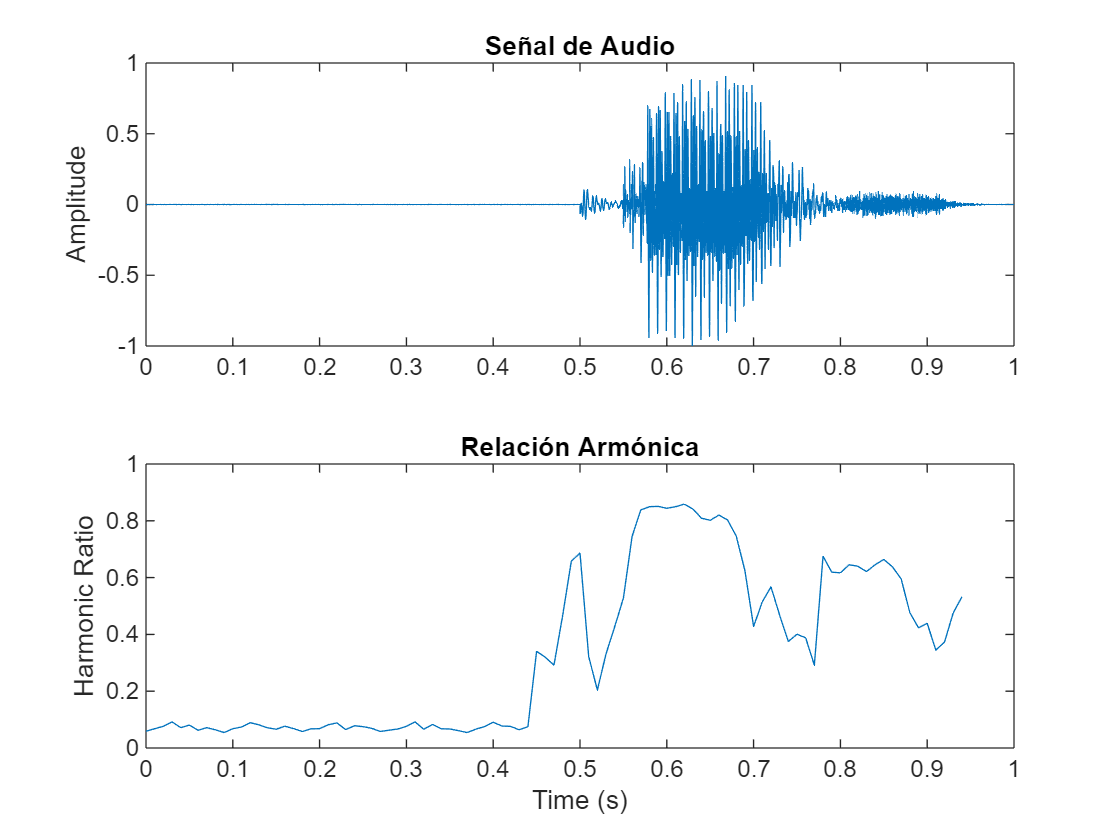

% Este bloque calcula la relación armónica para identificar regiones de voz.

hr = harmonicRatio(xBuff_PEF, fs, ...
                   'Window', hamming(size(xBuff_PEF, 1), "periodic"), ...
                   'OverlapLength', 0);

% Crear eje temporal para la relación armónica
t_hr = (0:(length(hr)-1)) * HOPLENGTH;

% Graficar el audio y la relación armónica
figure;
tiledlayout(2, 1);

nexttile;
plot(t_audio, x);
ylabel("Amplitude");
title("Señal de Audio");

nexttile;
plot(t_hr, hr);
ylabel("Harmonic Ratio");
xlabel("Time (s)");
title("Relación Armónica");

disp('Relación armónica calculada y graficada.');

Relación armónica calculada y graficada.


## Calcular la Mediana a Largo Plazo

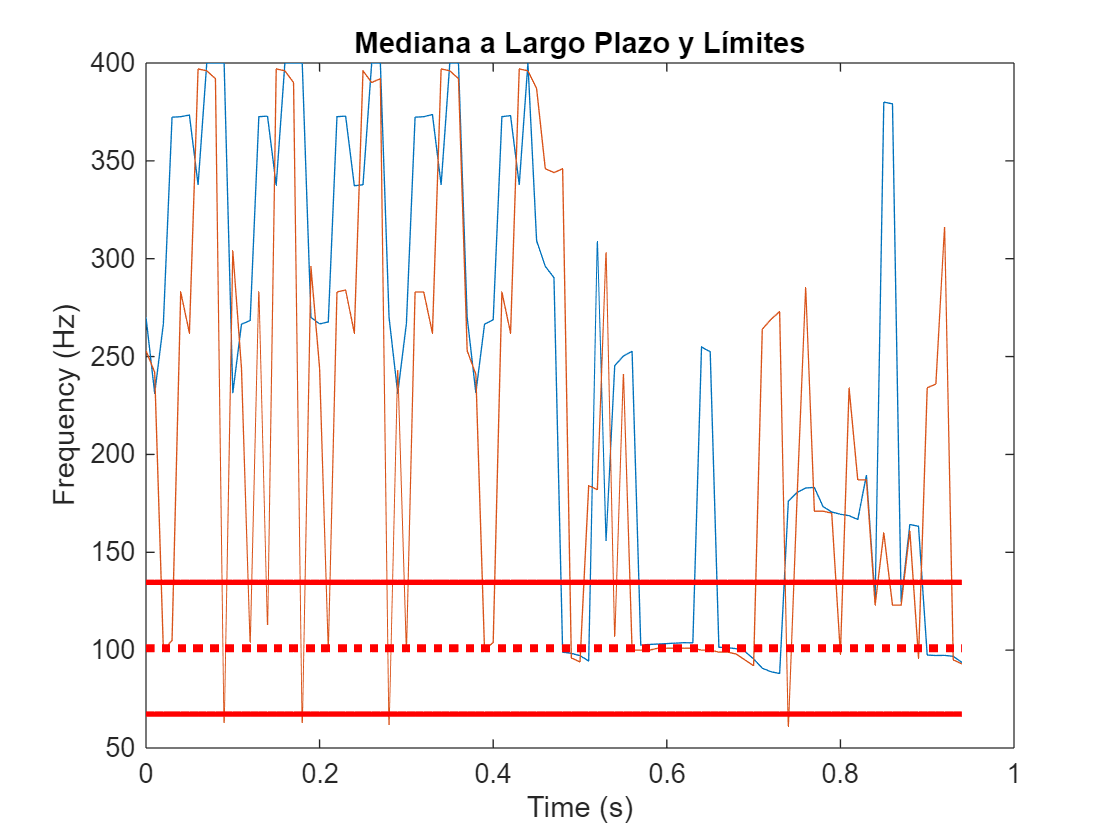

% Este bloque calcula la mediana a largo plazo basándose en regiones de voz.

% Identificar regiones de habla utilizando un umbral
idxToKeep = logical(movmedian(hr > ((3/4) * max(hr)), 3));

% Calcular la mediana a largo plazo
longTermMedian = median([f0_PEF(idxToKeep, 1); f0_SRH(idxToKeep, 1)]);

% Definir límites inferior y superior para los candidatos
lower = max((2/3) * longTermMedian, RANGE(1));
upper = min((4/3) * longTermMedian, RANGE(2));

% Graficar los candidatos y los límites
figure;
plot(t_f0, [f0_PEF(:, 1), f0_SRH(:, 1)]);
hold on;
plot(t_f0, longTermMedian .* ones(size(f0_PEF, 1), 1), "r:", 'LineWidth', 3);
plot(t_f0, upper .* ones(size(f0_PEF, 1), 1), "r", 'LineWidth', 2);
plot(t_f0, lower .* ones(size(f0_PEF, 1), 1), "r", 'LineWidth', 2);
hold off;
xlabel("Time (s)");
ylabel("Frequency (Hz)");
title("Mediana a Largo Plazo y Límites");

disp('Mediana a largo plazo calculada y graficada.');

Mediana a largo plazo calculada y graficada.


# Paso 3: Reducción de Candidatos

## Reducir la Confianza de Candidatos Fuera de los Límites

% Este bloque reduce la confianza de los candidatos fuera de los límites definidos.

% Reducir confianza para candidatos PEF fuera de los límites
invalid_PEF = f0_PEF < lower | f0_PEF > upper;
conf_PEF(invalid_PEF) = conf_PEF(invalid_PEF) / 10;

% Ordenar candidatos PEF por confianza en orden descendente
[conf_PEF, order_PEF] = sort(conf_PEF, 2, "descend");
for i = 1:size(f0_PEF, 1)
    f0_PEF(i, :) = f0_PEF(i, order_PEF(i, :));
end

% Reducir confianza para candidatos SRH fuera de los límites
invalid_SRH = f0_SRH < lower | f0_SRH > upper;
conf_SRH(invalid_SRH) = conf_SRH(invalid_SRH) / 10;

% Ordenar candidatos SRH por confianza en orden descendente
[conf_SRH, order_SRH] = sort(conf_SRH, 2, "descend");
for i = 1:size(f0_SRH, 1)
    f0_SRH(i, :) = f0_SRH(i, order_SRH(i, :));
end

disp('Confianza ajustada para candidatos fuera de los límites.');

Confianza ajustada para candidatos fuera de los límites.


## Concatenar y Seleccionar Candidatos Más Confiables

% Este bloque combina los candidatos más confiables de PEF y SRH.

% Combinar los dos candidatos más confiables de cada algoritmo
candidates = [f0_PEF(:, 1:2), f0_SRH(:, 1:2)];
confidence = [conf_PEF(:, 1:2), conf_SRH(:, 1:2)];

disp('Candidatos reducidos y concatenados.');

Candidatos reducidos y concatenados.


## Graficar los Candidatos Reducidos

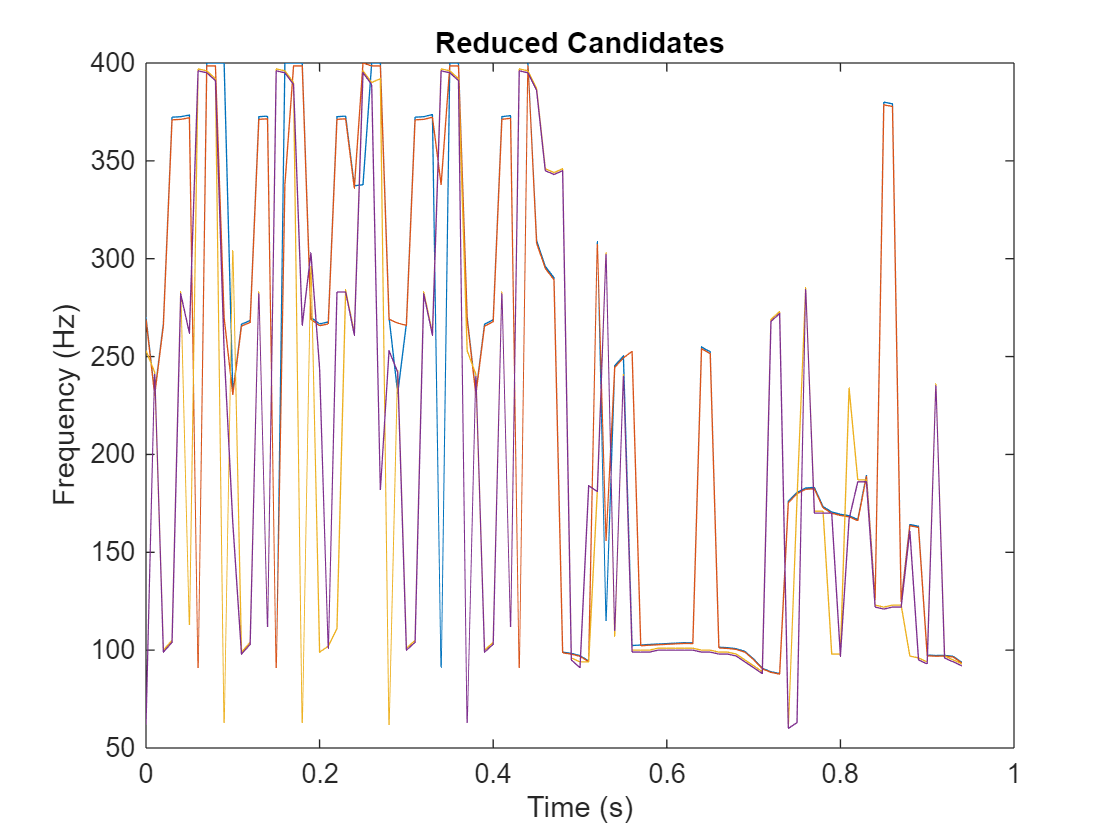

% Este bloque grafica los candidatos después de la reducción.

figure;
plot(t_f0, candidates);
xlabel("Time (s)");
ylabel("Frequency (Hz)");
title("Reduced Candidates");

disp('Candidatos reducidos graficados.');

Candidatos reducidos graficados.


# Paso 4: Hacer los Candidatos Distintivos

## Ajustar Candidatos Cercanos

% Este bloque ajusta los candidatos que están dentro de un rango de 5 Hz.

% Parámetros para ajustar candidatos
span = 5; % Rango en Hz para considerar candidatos cercanos
confidenceFactor = 1; % Factor para ajustar la confianza

% Ajustar candidatos y su confianza
for r = 1:size(candidates, 1)
    for c = 1:size(candidates, 2)
        % Identificar candidatos cercanos dentro del rango de 5 Hz
        tf = abs(candidates(r, c) - candidates(r, :)) < span;
        
        % Ajustar el candidato actual al promedio de los cercanos
        candidates(r, c) = mean(candidates(r, tf));
        
        % Sumar la confianza de los candidatos cercanos
        confidence(r, c) = sum(confidence(r, tf)) * confidenceFactor;
    end
end

disp('Candidatos ajustados para ser distintivos.');

Candidatos ajustados para ser distintivos.


## Limitar los Candidatos al Rango Permitido

% Este bloque asegura que los candidatos estén dentro del rango [50, 400] Hz.

% Limitar valores de candidatos al rango especificado
candidates = max(min(candidates, 400), 50);

disp('Candidatos limitados al rango permitido.');

Candidatos limitados al rango permitido.


## Graficar los Candidatos Ajustados

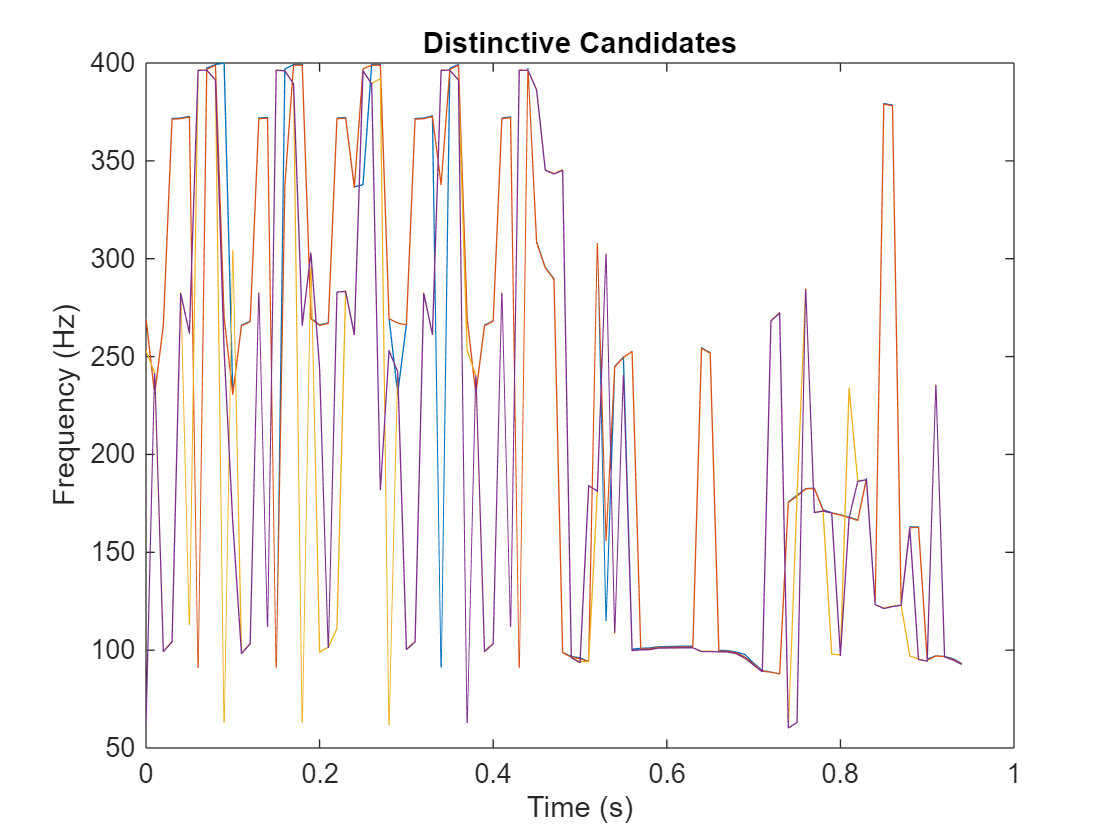

% Este bloque grafica los candidatos después de hacerlos distintivos.

figure;
plot(t_f0, candidates);
xlabel("Time (s)");
ylabel("Frequency (Hz)");
title("Distinctive Candidates");

disp('Candidatos distintivos graficados.');

Candidatos distintivos graficados.


# Paso 5: Iteración Hacia Adelante del HMM con Suavizado de Octavas

## Cargar la Matriz de Emisión y Rango Asociado

% Carga la matriz de emisión y define los rangos para probabilidades de transición.
load('EmissionMatrix.mat', 'emissionMatrix', 'emissionMatrixRange');
disp('Matriz de emisión y rango asociado cargados.');

Matriz de emisión y rango asociado cargados.


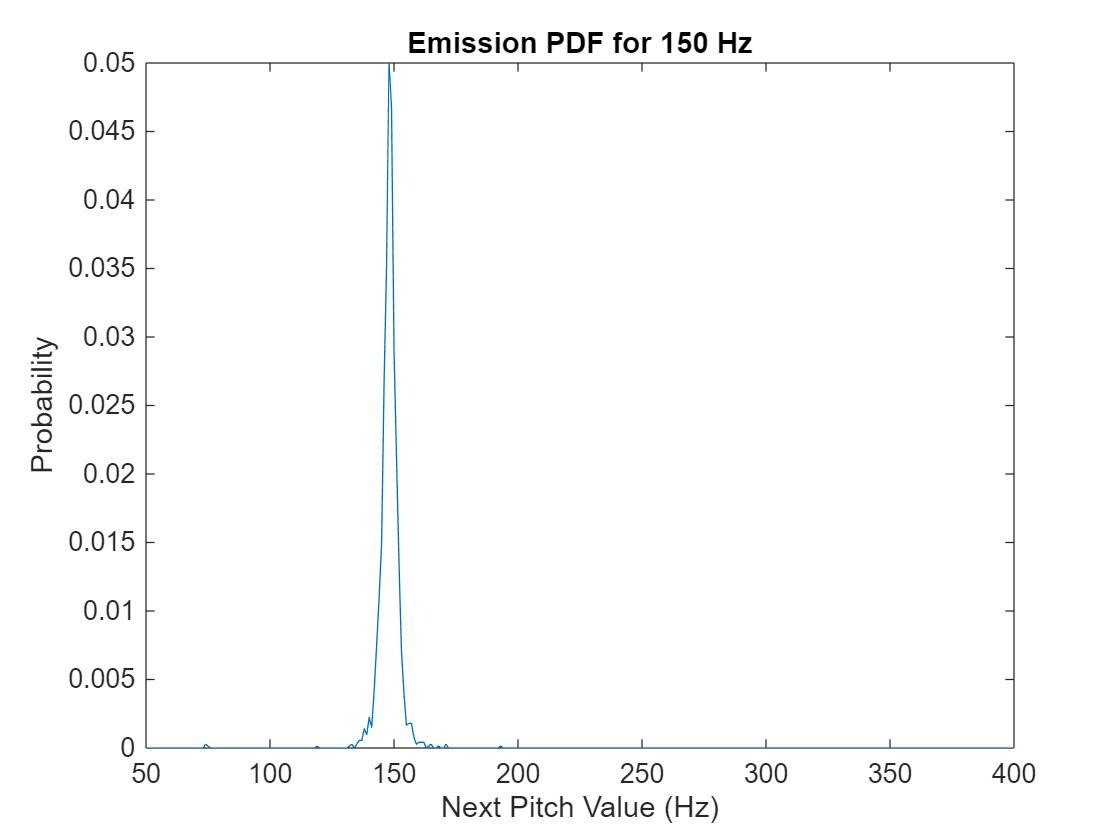


% Graficar la PDF de emisión para un estado específico (150 Hz)
currentState = 150;
figure;
plot(emissionMatrixRange(1):emissionMatrixRange(2), ...
     emissionMatrix(currentState - emissionMatrixRange(1) - 1, :));
title("Emission PDF for " + currentState + " Hz");
xlabel("Next Pitch Value (Hz)");
ylabel("Probability");

disp('PDF de emisión graficada.');

PDF de emisión graficada.


## Preasignación de Variables

% Inicializar variables para la iteración hacia adelante del HMM.
numPaths = 4; % Número de caminos
numHops = size(candidates, 1); % Número de saltos temporales
logbook = zeros(numHops, 3, numPaths); % Registro de estados
suspectHops = zeros(numHops, 1); % Saltos sospechosos

disp('Variables preasignadas para la iteración hacia adelante.');

Variables preasignadas para la iteración hacia adelante.


## Iteración Hacia Adelante con Suavizado de Octavas

% Iterar sobre cada hop temporal para calcular las probabilidades de transición.
for hopNumber = 1:numHops
    nowCandidates = candidates(hopNumber, :);
    nowConfidence = confidence(hopNumber, :);
    
    % Manejo de saltos de octava después de 100 hops
    if hopNumber > 100
        % Mediana ponderada a corto plazo
        medianWindowLength = 50;
        aTemp = logbook(max(hopNumber - medianWindowLength, 1):hopNumber - 1, 1, :);
        shortTermMedian = median(aTemp(:));
        previousM = mean([longTermMedian, shortTermMedian]);
        
        % Definir límites ajustados
        lowerTight = max((4/3) * previousM, emissionMatrixRange(1));
        upperTight = min((2/3) * previousM, emissionMatrixRange(2));
        numCandidateOutside = sum(nowCandidates < lowerTight | nowCandidates > upperTight);
        
        % Añadir candidatos de respaldo si hay saltos de octava
        if numCandidateOutside > 0
            nowCandidates = [nowCandidates, BackupCandidates(hopNumber, :)]; %#ok<AGROW>
            nowConfidence = [nowConfidence, repmat(mean(nowConfidence), 1, 2)]; %#ok<AGROW>
            
            % Hacer los nuevos candidatos distintivos
            span = 10;
            confidenceFactor = 1.2;
            for r = 1:size(nowCandidates, 1)
                for c = 1:size(nowCandidates, 2)
                    tf = abs(nowCandidates(r, c) - nowCandidates(r, :)) < span;
                    nowCandidates(r, c) = mean(nowCandidates(r, tf));
                    nowConfidence(r, c) = sum(nowConfidence(r, tf)) * confidenceFactor;
                end
            end
        end
    end
    
    % Crear la matriz de confianza
    confidenceMatrix = zeros(numel(nowCandidates), size(logbook, 3));
    for pageIdx = 1:size(logbook, 3)
        if hopNumber ~= 1
            pastPitch = floor(logbook(hopNumber - 1, 1, pageIdx)) - emissionMatrixRange(1) + 1;
        else
            pastPitch = nan;
        end
        for candidateNumber = 1:numel(nowCandidates)
            if hopNumber ~= 1
                % Calcular la probabilidad de transición
                currentPitch = floor(nowCandidates(candidateNumber)) - emissionMatrixRange(1) + 1;
                confidenceMatrix(candidateNumber, pageIdx) = ...
                    emissionMatrix(currentPitch, pastPitch) * ...
                    logbook(hopNumber - 1, 2, pageIdx) * ...
                    nowConfidence(candidateNumber);
            else
                confidenceMatrix(candidateNumber, pageIdx) = 1;
            end
        end
    end
    
    % Asignar la mejor estimación para cada camino
    for pageIdx = 1:size(logbook, 3)
        [~, idx] = max(confidenceMatrix(:));
        [chosenPitch, pastPitchIdx] = ind2sub(size(confidenceMatrix), idx);
        logbook(hopNumber, :, pageIdx) = ...
            [nowCandidates(chosenPitch), ...
            confidenceMatrix(chosenPitch, pastPitchIdx), ...
            pastPitchIdx];
        confidenceMatrix(chosenPitch, :) = NaN;
    end
    
    % Normalizar la confianza
    logbook(hopNumber, 2, :) = logbook(hopNumber, 2, :) / sum(logbook(hopNumber, 2, :));
end

disp('Iteración hacia adelante del HMM completada.');

Iteración hacia adelante del HMM completada.


# Paso 6: Traceback of HMM

## Inicializar variables

% Determinar el contorno final de pitch usando el registro del HMM.
numHops = size(logbook, 1);
keepLooking = true;
index = numHops + 1;

% Encontrar el último hop con información válida
while keepLooking
    index = index - 1;
    if abs(max(logbook(index, 2, :)) - min(logbook(index, 2, :))) ~= 0
        keepLooking = false;
    end
end

% Identificar el índice del mejor camino
[~, bestPathIdx] = max(logbook(index, 2, :));
bestIndices = zeros(numHops, 1);
bestIndices(index) = bestPathIdx;

% Retroceder para construir el mejor camino
for ii = index:-1:2
    bestIndices(ii - 1) = logbook(ii, 3, bestIndices(ii));
end

% Reemplazar valores cero por 1 (en caso de índices vacíos)
bestIndices(bestIndices == 0) = 1;

## Construir el contorno de pitch final

% Inicializar el contorno de pitch (f0)
f0 = zeros(numHops, 1);

% Llenar el contorno con los valores del logbook
for ii = numHops:-1:2
    f0(ii) = logbook(ii, 1, bestIndices(ii));
end

## Determinar regiones sonorizadas

% Usar el Harmonic Ratio (hr) para definir `isVoiced`
isVoiced = hr > (0.75 * max(hr)); % Ajusta el umbral según tu señal

% Filtrar valores no sonorizados
f0toPlot = f0;  % Convierte a vector fila

f0toPlot(~isVoiced) = NaN;

## Calcular Gross Pitch Error (GPE)

% Definir el eje temporal para los frames
HOPLENGTH = 0.01; % Duración del hop en segundos
t0 = (0:size(candidates, 1)-1) * HOPLENGTH;

% Cargar el contorno de pitch verdadero desde el archivo
load('TruePitch.mat', 'truePitch'); % Cargar solo la variable 'truePitch'

% Crear t_truePitch en función de la longitud de truePitch
fs = 44100; % Frecuencia de muestreo utilizada
t_truePitch = (0:length(truePitch)-1) / fs; % Generar el eje temporal asociado


% Expandir t_truePitch para cubrir todo el rango de t0
t_truePitch_expanded = linspace(min(t0), max(t0), length(truePitch));

% Ajustar el contorno de pitch de referencia al eje temporal actual
truePitch_adjusted = interp1(t_truePitch_expanded, truePitch, t0, 'linear', 'extrap');


% Definir el margen de error relativo permitido
p = 0.1; % 10%


% Calcular el GPE
GPE = mean(abs(f0toPlot(isVoiced) - truePitch_adjusted(isVoiced)) > ...
           truePitch_adjusted(isVoiced) .* p) .* 100;


% Mostrar el GPE calculado
disp(['Gross Pitch Error (GPE): ', num2str(GPE), ' %']);

Gross Pitch Error (GPE): 0             0             0             0             0             0             0             0             0             0             0             0      89.47368             0             0             0             0      21.05263           100 %


## Graficar el contorno de pitch final

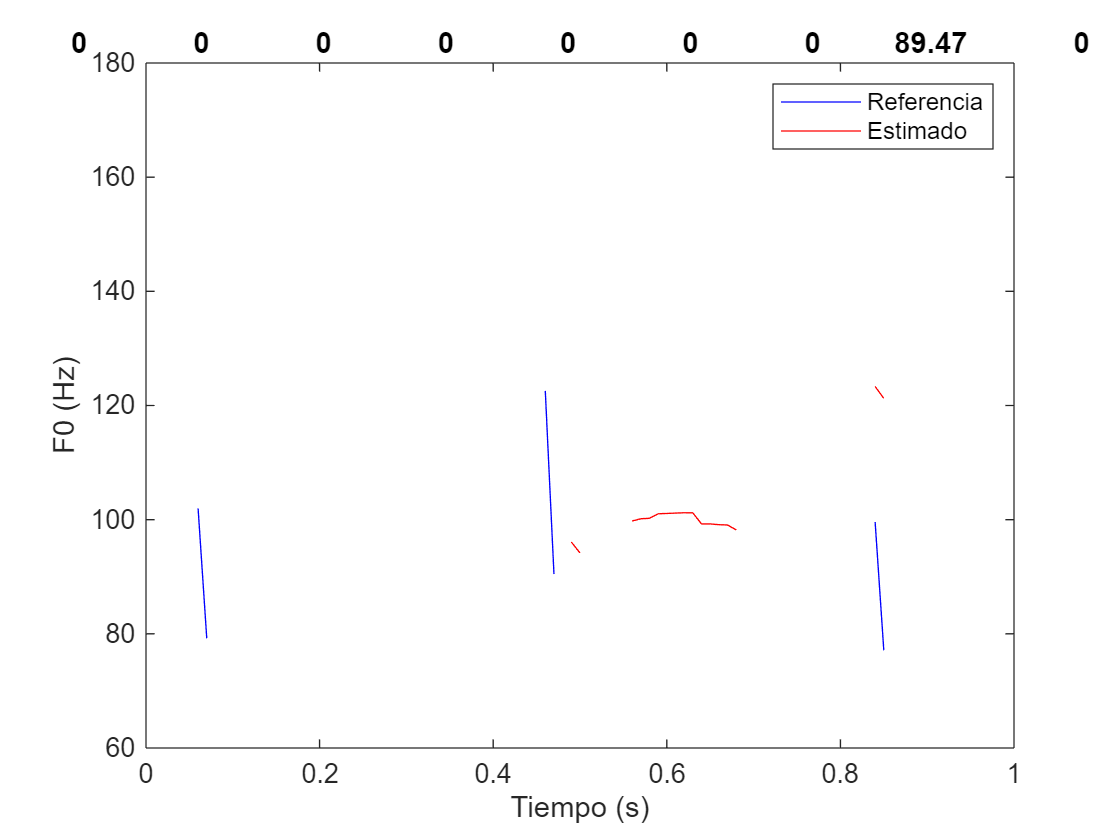

figure;
plot(t0, truePitch_adjusted, 'b', 'DisplayName', 'Referencia');
hold on;
plot(t0, f0toPlot, 'r', 'DisplayName', 'Estimado');
hold off;
legend();
ylabel('F0 (Hz)');
xlabel('Tiempo (s)');
title(['GPE = ', num2str(round(GPE, 2)), ' (%)']);

# Paso 7: Moving Median Filter

## Aplicar un filtro mediano móvil

% Usar un filtro mediano móvil con una ventana de 3 saltos para suavizar el contorno de pitch estimado
f0_filtered = movmedian(f0, 3);
f0_filtered(~isVoiced) = NaN; % Eliminar valores en regiones no sonorizadas

## Calcular el Gross Pitch Error (GPE) final

% Recalcular el GPE después de aplicar el filtro
GPE_final = mean(abs(f0_filtered(isVoiced) - truePitch_adjusted(isVoiced)) > ...
                 truePitch_adjusted(isVoiced) .* p) .* 100;

% Mostrar el GPE final
disp(['Gross Pitch Error (GPE) final: ', num2str(GPE_final), ' %']);

Gross Pitch Error (GPE) final: 0             0             0             0             0             0             0             0             0             0             0             0      89.47368             0             0             0             0      21.05263           100 %


## Visualizar el contorno de pitch final

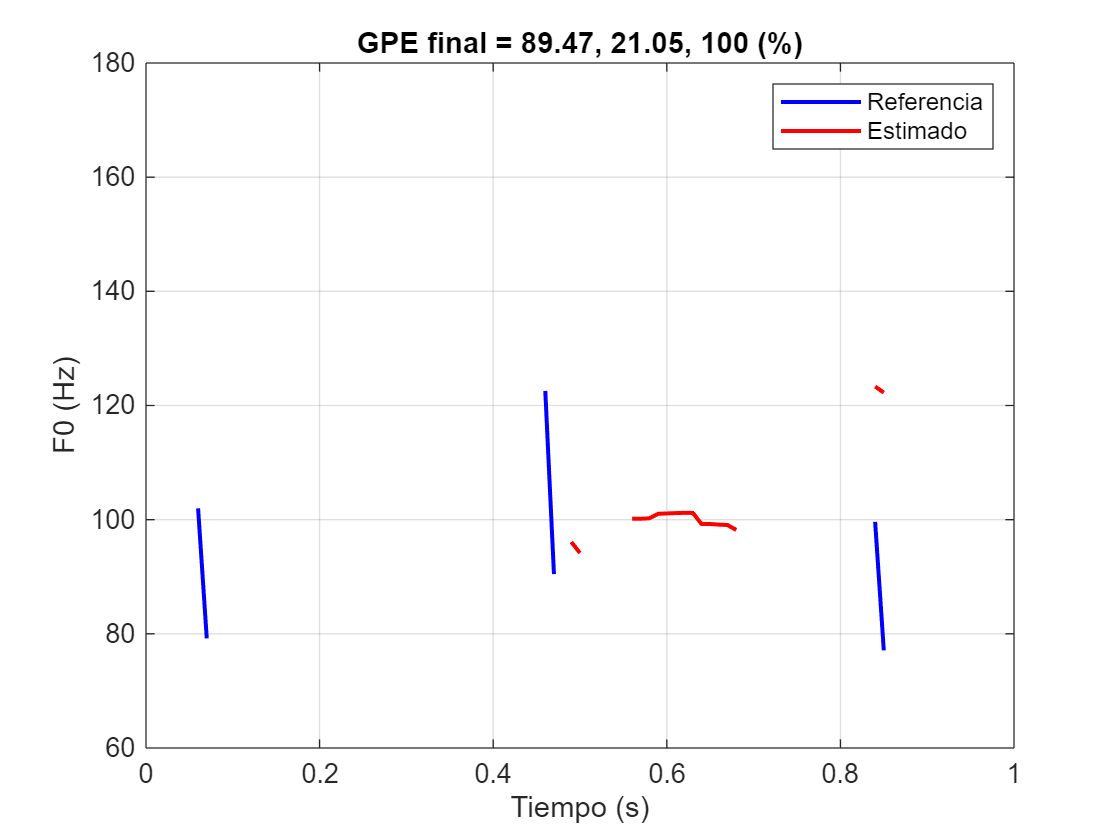

% Filtrar los valores del GPE final que son diferentes de 0
relevantGPE = GPE_final(GPE_final ~= 0);

% Convertir los valores relevantes en una cadena para el título
if isempty(relevantGPE)
    titleText = "GPE final = 0% (sin errores significativos)";
else
    titleText = "GPE final = " + join(string(round(relevantGPE, 2)), ", ") + " (%)";
end

%% Visualizar el contorno de pitch final con título ajustado
figure;
plot(t0, truePitch_adjusted, 'b', 'LineWidth', 1.5); hold on;
plot(t0, f0_filtered, 'r', 'LineWidth', 1.5);
legend("Referencia", "Estimado");
ylabel("F0 (Hz)");
xlabel("Tiempo (s)");
title(titleText); % Aplicar el título ajustado
grid on;
hold off;